% side_quest_visualize_binning_effects.m
%
% Script to visualize the effect of different binning factors on an FTIR spectrum.
% Uses tiledlayout for a compact presentation.
%
% Date: 2025-05-16

%% 0. Initialization
clear; clc; close all;
fprintf('Visualizing Binning Effects - %s\n', string(datetime('now')));

Visualizing Binning Effects - 16-May-2025 20:59:28



% --- Define Paths (Simplified) ---
projectRoot = pwd; % Assumes current working directory IS the project root.
if ~exist(fullfile(projectRoot, 'src'), 'dir') || ~exist(fullfile(projectRoot, 'data'), 'dir')
    error(['Project structure not found. Please ensure MATLAB''s "Current Folder" is set to your ' ...
           'main project root directory before running. Current directory is: %s'], projectRoot);
end
srcPath       = fullfile(projectRoot, 'src');
helperFunPath = fullfile(srcPath, 'helper_functions');
if ~exist(helperFunPath, 'dir')
    error('The ''helper_functions'' directory was not found inside ''%s''.', srcPath);
end
addpath(helperFunPath); % For bin_spectra function
dataPath      = fullfile(projectRoot, 'data');
figuresPath   = fullfile(projectRoot, 'figures', 'SideQuests'); % New folder for this plot
if ~exist(figuresPath, 'dir'), mkdir(figuresPath); end
dateStr = string(datetime('now','Format','yyyyMMdd'));

%% 1. Load Data for Visualization
% We need one representative spectrum and the original wavenumbers.
% Let's use the mean spectrum of the entire training set for illustration.
fprintf('Loading training data to calculate mean spectrum...\n');

Loading training data to calculate mean spectrum...


trainingDataFile = fullfile(dataPath, 'training_set_no_outliers_T2Q.mat');
try
    loadedTrainingData = load(trainingDataFile, 'X_train_no_outliers');
    X_train_full = loadedTrainingData.X_train_no_outliers;

    wavenumbers_data = load(fullfile(dataPath, 'wavenumbers.mat'), 'wavenumbers_roi');
    wavenumbers_original = wavenumbers_data.wavenumbers_roi;
    
    % Calculate the mean spectrum from the entire training set
    if ~isempty(X_train_full)
        mean_spectrum_original = mean(X_train_full, 1);
        fprintf('Using mean spectrum of training data for visualization.\n');
    else
        error('Training data (X_train_no_outliers) is empty or not loaded.');
    end
    
catch ME
    fprintf('ERROR loading data: %s\n', ME.message);
    return;
end

Using mean spectrum of training data for visualization.



if length(mean_spectrum_original) ~= length(wavenumbers_original)
    error('Mismatch between mean spectrum length (%d) and wavenumbers length (%d).', ...
        length(mean_spectrum_original), length(wavenumbers_original));
end

%% 2. Define Binning Factors to Visualize
% =========================================================================
binningFactorsToVisualize = [1, 2, 4, 8, 16];
numPlots = length(binningFactorsToVisualize);

%% 3. Create Plot with Tiled Layout
% =========================================================================
fprintf('Generating plot with tiled layout to show binning effects...\n');

Generating plot with tiled layout to show binning effects...


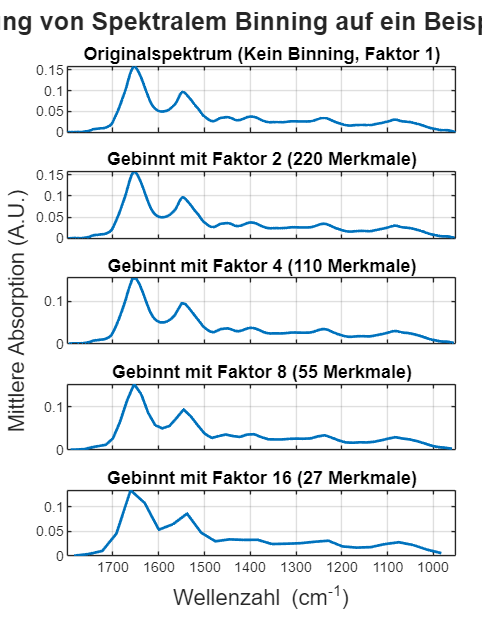


figure('Name', 'Effect of Spectral Binning', 'Position', [100, 100, 700, 900]); % Taller figure
t = tiledlayout(numPlots, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Auswirkung von Spektralem Binning auf ein Beispielspektrum', 'FontSize', 14, 'FontWeight', 'bold');
xlabel(t, 'Wellenzahl (cm^{-1})', 'FontSize', 12);
ylabel(t, 'Mittlere Absorption (A.U.)', 'FontSize', 12); % This will be a shared ylabel

for i = 1:numPlots
    binFactor = binningFactorsToVisualize(i);
    
    ax = nexttile; % Create next tile (subplot)
    
    if binFactor == 1
        % Plot original mean spectrum
        current_spectrum_to_plot = mean_spectrum_original;
        current_wavenumbers_to_plot = wavenumbers_original;
        plotTitle = 'Originalspektrum (Kein Binning, Faktor 1)';
    else
        % Apply binning
        [binned_spectrum, binned_wavenumbers] = bin_spectra(mean_spectrum_original, wavenumbers_original, binFactor);
        current_spectrum_to_plot = binned_spectrum;
        current_wavenumbers_to_plot = binned_wavenumbers;
        plotTitle = sprintf('Gebinnt mit Faktor %d (%d Merkmale)', binFactor, length(binned_wavenumbers));
    end
    
    if ~isempty(current_spectrum_to_plot) && ~isempty(current_wavenumbers_to_plot)
        plot(ax, current_wavenumbers_to_plot, current_spectrum_to_plot, 'LineWidth', 1.5);
        title(ax, plotTitle, 'FontSize', 10);
        grid(ax, 'on');
        ax.XDir = 'reverse'; % Typical for spectra
        
        % Set common y-limits for better comparison if desired, or let them auto-scale
        % ylim(ax, [min(mean_spectrum_original)-0.05 max(mean_spectrum_original)+0.05]);
        
        if ~isempty(wavenumbers_original)
             xlim(ax, [min(wavenumbers_original) max(wavenumbers_original)]); % Keep original x-range view
        end
    else
        title(ax, sprintf('Binning Faktor %d - Keine Daten zu plotten', binFactor), 'FontSize', 10);
    end
    
    % Only show x-axis label on the bottom plot
    if i < numPlots
        set(ax, 'XTickLabel', []);
    end
end

% Save the figure
binningEffectPlotFilenameBase = fullfile(figuresPath, sprintf('%s_SideQuest_BinningEffects', dateStr));
savefig(gcf, [binningEffectPlotFilenameBase, '.fig']);
exportgraphics(gcf, [binningEffectPlotFilenameBase, '.tiff'], 'Resolution', 300);

fprintf('Binning effect visualization plot saved to: %s.(fig/tiff)\n', binningEffectPlotFilenameBase);

Binning effect visualization plot saved to: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\SideQuests\20250516_SideQuest_BinningEffects.(fig/tiff)



fprintf('\nBinning visualization script complete.\n');


Binning visualization script complete.
